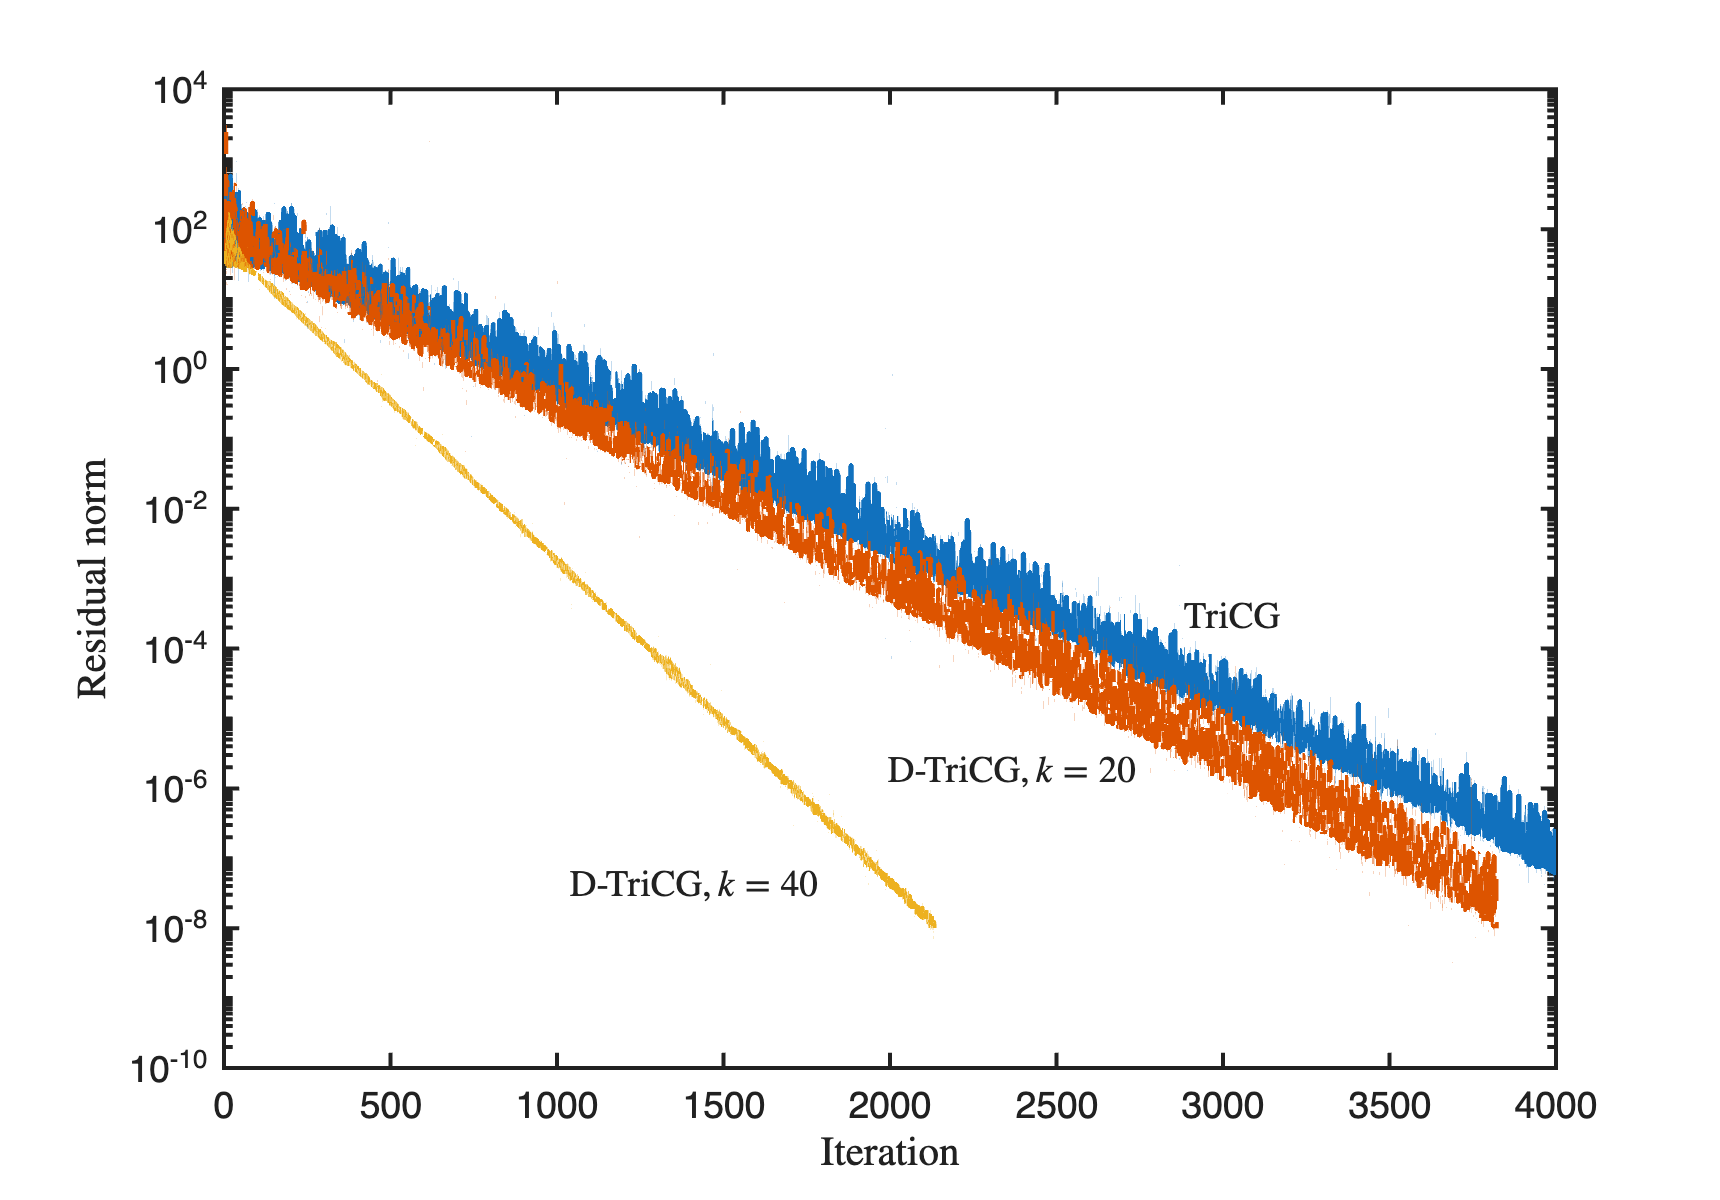

clc; close all; clearvars;

A = [linspace(0, 100, 1960), linspace(1000, 1020, 40)]';
m = length(A);
n = m;
A = spdiags(A, 0, m, n);

rng(100);
b1 = randn(m, 1);
c1 = randn(n, 1);

b2 = rand(m, 1);
c2 = rand(n, 1);

tol = 1e-8;
stol = 1e-12;
exres = true;
maxit = 4000;

[~, ~, ~, resvec1] = tricg(A, b2, c2, [], [], tol, maxit, exres=exres);


default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 860 600]);

semilogy(0:length(resvec1)-1, resvec1, LineStyle='-');
hold on;

ks = [20, 40];
maxcycle = 60;

% lgd_title = cell(1, 1+length(ks));
% lgd_title{1} = 'TriCG';

line_style = {'--', '-.', ':'};
for i = 1:length(ks)
    k = ks(i);
    p = 40 + k;
    [U, S, V, MU, NV, T, l] = gssydr(A, b1, c1, [], [], k, p, stol, maxcycle);

    d = [eye(k), T(1:k, 1:k); T(1:k, 1:k)', -eye(k)] \ [U(:,1:k)'*b2; V(:,1:k)'*c2];
    d = [eye(k+1, k), T(1:k+1, 1:k); T(1:k, 1:k+1)', -eye(k+1, k)] * d;
    rx = b2 - MU(:, 1:k+1) * d(1:k+1);
    ry = c2 - NV(:, 1:k+1) * d(k+2:end);

    [~, ~, ~, resvec2] = tricg(A, rx, ry, [], [], tol, maxit, exres=exres, ...
        augU=U(:, 1:l), augMU=MU(:, 1:l), augV=V(:, 1:l), augNV=NV(:, 1:l));

    % lgd_title{i+1} = sprintf('D-TriCG, $k=%d\\ $', k);
    semilogy(0:length(resvec2)-1, resvec2, LineStyle=line_style{i});
end
hold off;

xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
% legend(lgd_title, Location='northeast', Interpreter='latex', FontSize=14);

annotation("textbox", [0.5063 0.3352 0.152 0.04874], "String", "D-TriCG$,k=20$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex")
annotation("textbox", [0.3211 0.2401 0.152 0.04874], "String", "D-TriCG$,k=40$", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex")
annotation("textbox", [0.6785 0.4638 0.0903 0.04874], "String", "TriCG", ...
            "FontSize", 14, "LineStyle", "none", "Interpreter", "latex")

exportgraphics(gcf, 'figs/fig4.pdf', Resolution=600);